clear all;
clc;

L = 130e-6;
dsl = 0.625;
dso = 0;
st_turns= 4;
rt_turns = 20;
r = 0.0642;
g0 = 1.6e-3;
i=1;
j=1;

data_size = 100;
h_size = 100;
gamma = ((11*pi)/180);
theta_r = linspace(0, 2*pi, data_size);
phi = linspace(0, 2*pi, data_size);
z = linspace(0, L, data_size);
d = 0.3;

mu_0 = 4* pi* 10e-7;

r_t_for_theta = zeros(data_size, data_size);
r_w_for_theta = zeros(data_size, data_size);
s_w = zeros(data_size, data_size);

Lxy_mat = zeros( data_size, data_size);

k = data_size;
dz = L / k;
z_midpoints = linspace(dz/2, L-dz/2, k);
G_for_z = zeros(data_size, data_size);
% Calculate stator Turns
s_t = ((38*st_turns)/15)*ones(size(phi));
for h = 1:h_size
    sum1 = (((st_turns)/(pi*h)) * (cos(2*h*(phi-(((i-1)*pi)/3))))) *((2*sin((2*h*pi)/5) + (2*sin((2*h*4*pi)/15)) - (2*sin((2*h*11*pi)/15)) - (2*sin((2*h*4*pi)/5)) + (sin((2*h*pi)/3)) - (sin((2*2*h*pi)/3))));
    sum2 = (((st_turns)/(pi*h)) * (sin(2*h*(phi-(((i-1)*pi)/3))))) * ((5 - (2*cos((2*h*pi)/5)) - (2*cos((2*h*4*pi)/15)) + (2*cos((2*h*11*pi)/15)) + (2*cos((2*h*4*pi)/5)) - (cos(2*h*pi/3)) + (cos((2*2*h*pi)/3)) - (5*cos(2*h*pi))));
    s_t = (s_t + sum1 + sum2)  ;
end

for t_i = 1:data_size
    % Rotor turns function
    r_t = 0;
    for h = 1:h_size
        sum1 = (((rt_turns)/(pi*h)) * (cos(2*h*(phi- theta_r(t_i)-(((j-1)*pi)/3))))) *((sin((h*pi)/3) + (2*sin((h*pi)/2)) + (sin((2*h*pi)/3)) - (2*sin((h*3*pi)/2)) - (sin((4*h*pi)/3)) - (sin((5*h*pi)/3))));
        sum2 = (((rt_turns)/(pi*h)) * (sin(2*h*(phi-theta_r(t_i)-(((j-1)*pi)/3))))) * ((4 - (cos((h*pi)/3)) - (2*cos((h*pi)/2)) - (cos((2*h*pi)/3)) +(2*cos((3*h*pi)/2))+ (cos((h*4*pi)/3)) + (cos(5*h*pi/3)) - (4*cos(2*h*pi))));
        r_t = (r_t + sum1 + sum2 );
    end
    r_t_for_theta(t_i, :) = r_t + (2*rt_turns);
    s_w_temp = 0;
    r_w_temp = 0;
    L_yx_temp = 0;
    for i_z = 1: data_size
        % Calculate Air Gap function
        z_j = z_midpoints(i_z);
        d_z = (((dsl-dso)/L)*z_j)+(dso);
        G = g0 * (1 - (d_z .* cos(phi)));
        G_for_z(:, i_z)= G;
        
        
        s_w_temp = (winding_function_S(L, phi, z_j, G, s_t)+ s_w_temp)*dz;
        s_w(:, i_z) = s_t - s_w_temp;
        r_w_temp = (winding_function_S(L, phi, z_j, G, r_t_for_theta(t_i, :)) + r_w_temp)*dz;
        r_w_for_theta(t_i, :)  =  r_t_for_theta(t_i, :) -r_w_temp;
        temp = 0;
        % integrand = r .* r_t_for_theta(t_i, :) .* s_w(:, i_z)' ./ (G);

        integrand = r .* r_t_for_theta(t_i, :) .* r_w_for_theta(t_i, :) ./ (G);
        L_yx_temp = mu_0 * dz * (trapz(phi, integrand) + L_yx_temp);
        Lxy_mat(t_i, i_z) = L_yx_temp;

    end
end


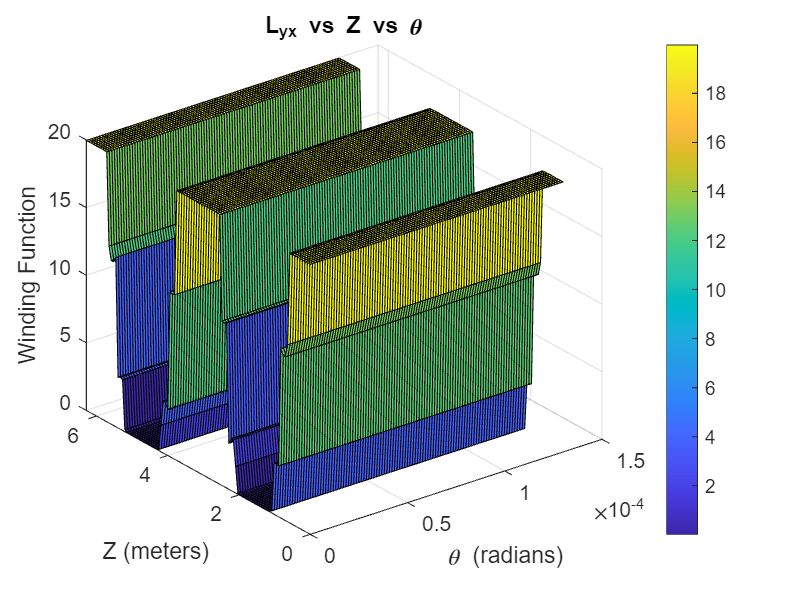


 % plot_phi(phi, s_w, '\phi', 'n_{si}(\phi)');
% plot_phi(phi, nri_list(1, :), '\phi', 'n_{ri}(\phi)');
% plot_phi_for_each_z(phi, G, 'Phi (rad)', 'g (m)');

[Z, Phi] = meshgrid(z, phi);
% plot_surf(Phi, Z, G_for_z, 'Phi (radians)', 'Z (meters)', 'G (meters)', 'G vs Phi vs Z');

% plot_phi(phi, r_w_for_theta, '\phi', 'N_{s}(\phi)');
% plot_phi(phi, rotorwinding_data(20, :), '\phi', 'N_{r}(\phi)');

plot_surf(Z, Phi, s_w, '\theta (radians)', 'Z (meters)', 'Winding Function', 'L_{yx} vs Z vs \theta');

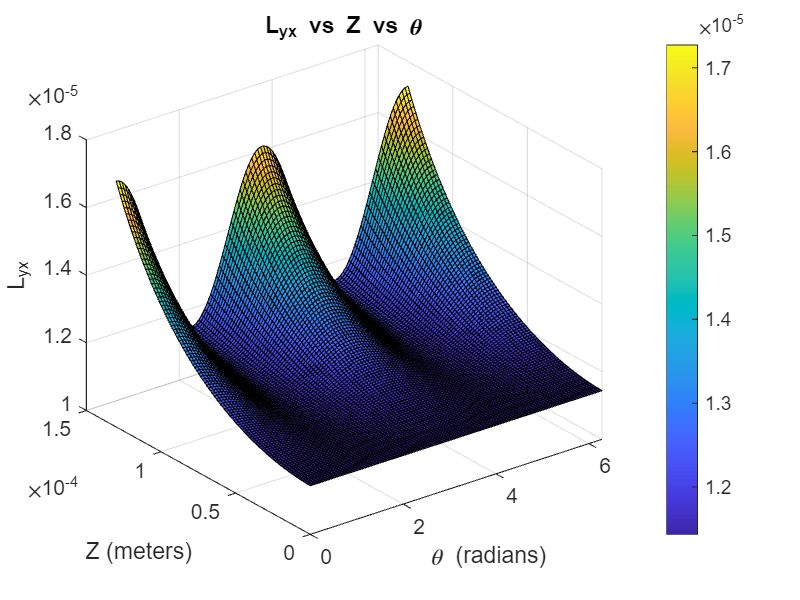


[Z_i, Theta] = meshgrid(z, theta_r);
plot_surf(Theta, Z_i, Lxy_mat, '\theta (radians)', 'Z (meters)', 'L_{yx}', 'L_{yx} vs Z vs \theta');

% % plot(Theta, L_yx,'red')
% ylabel('L_{yx}');
% xlabel('\theta (radians)');
% title('Inductance at end of Stack Length')

% plot_surf(Theta, Z_i, Lxy_mat{6, 1}, '\theta (radians)', 'Z (meters)', 'L_{yx}', 'L_{yx} vs Z vs \theta');
% % plot(Theta, L_yx,'red')
% ylabel('L_{yx}');
% xlabel('\theta (radians)');
% title('Inductance at end of Stack Length')



function turns_func_avg = winding_function_S(L, phi, z, G , func)
int_n_over_g = trapz( phi, func ./ G);
g_inv = 1./G;
g_avg = (1/(2*pi*L))*trapz( phi, g_inv);
turns_func_avg = (1/(2*pi*L*g_avg))*int_n_over_g;
end


function n_si = my_stator_turns_function(h_size, phi, N,i)
n_si = ((38*N)/15)*ones(size(phi));

for h = 1:h_size
    sum1 = (((N)/(pi*h)) * (cos(2*h*(phi-(((i-1)*pi)/3))))) *((2*sin((2*h*pi)/5) + (2*sin((2*h*4*pi)/15)) - (2*sin((2*h*11*pi)/15)) - (2*sin((2*h*4*pi)/5)) + (sin((2*h*pi)/3)) - (sin((2*2*h*pi)/3))));
    sum2 = (((N)/(pi*h)) * (sin(2*h*(phi-(((i-1)*pi)/3))))) * ((5 - (2*cos((2*h*pi)/5)) - (2*cos((2*h*4*pi)/15)) + (2*cos((2*h*11*pi)/15)) + (2*cos((2*h*4*pi)/5)) - (cos(2*h*pi/3)) + (cos((2*2*h*pi)/3)) - (5*cos(2*h*pi))));
    n_si = (n_si + sum1 + sum2)  ;
end
n_si = repmat(n_si, numel(n_si), 1);
end


function nri_list = my_rotor_turns_function(h_size, data_size, phi, N, theta_r,j)
nri_list = zeros(data_size);
for a = 1:data_size
    n_ri = 0;
    for h = 1:h_size
        sum1 = (((N)/(pi*h)) * (cos(2*h*(phi- theta_r(a)-(((j-1)*pi)/3))))) *((sin((h*pi)/3) + (2*sin((h*pi)/2)) + (sin((2*h*pi)/3)) - (2*sin((h*3*pi)/2)) - (sin((4*h*pi)/3)) - (sin((5*h*pi)/3))));
        sum2 = (((N)/(pi*h)) * (sin(2*h*(phi-theta_r(a)-(((j-1)*pi)/3))))) * ((4 - (cos((h*pi)/3)) - (2*cos((h*pi)/2)) - (cos((2*h*pi)/3)) +(2*cos((3*h*pi)/2))+ (cos((h*4*pi)/3)) + (cos(5*h*pi/3)) - (4*cos(2*h*pi))));
        n_ri = (n_ri + sum1 + sum2);
    end
    
    nri_list(a, :) = n_ri+ (2*N);
end
end



function plot_phi(phi, data, xlabel_text, ylabel_text)
plot(phi, data);
xlabel(xlabel_text);
ylabel(ylabel_text);
xticks([0, pi, 2*pi]);
xticklabels({'0', '\pi', '2\pi'});
grid on;
end


function plot_surf(x, y, z, xlabel_text, ylabel_text, zlabel_text, title_text)
figure;
surf(x, y, z);
xlabel(xlabel_text);
ylabel(ylabel_text);
zlabel(zlabel_text);
title(title_text);
colorbar;
end
